# Vehicle State Plotting

## Scenario setup

% Start the simulator
beamng = py.beamngpy.BeamNGpy('localhost', int32(64256));
% beamng = BeamNGpy('localhost', 64256, home='/path/to/bng/tech', user='/path/to/bng/tech/userfolder')

% beamng.open(listen_ip='*');  % Start up the simulator in Vulkan 11 Renderer .

beamng.open(py.list({string(missing),'Value'}), ...
    '-gfx', 'dx11', listen_ip='*') % Start up the simulator in DirectX 11 Renderer .

ans =   Python BeamNGpy with properties:

                     scenario: [1×1 py.beamngpy.api.beamng.scenario.ScenarioApi]
                   connection: [1×1 py.beamngpy.connection.connection.Connection]
                  set_gravity: [1×1 py.method]
                     show_hud: [1×1 py.method]
                         port: [1×1 py.int]
                          env: [1×1 py.beamngpy.api.beamng.environment.EnvironmentApi]
    get_current_vehicles_info: [1×1 py.method]
      load_trackbuilder_track: [1×1 py.method]
          set_relative_camera: [1×1 py.method]
                start_traffic: [1×1 py.method]
          add_debug_rectangle: [1×1 py.method]
                         step: [1×1 py.method]
           set_weather_preset: [1×1 py.method]
         remove_debug_spheres: [1×1 py.method]
                         user: [1×1 py.NoneType]
          get_part_annotation: [1×1 py.method]
       


% Create a vehicle
vehicle = py.beamngpy.Vehicle('ego_vehicle', pyargs('model', 'etk800', ...
                                                    'licence', 'Matlab', ...
                                                    'color', 'Green'));

% Create electrics sensor
electrics = py.beamngpy.sensors.Electrics();
vehicle.attach_sensor('electrics', electrics)

% Create scenario
scenario = py.beamngpy.Scenario('west_coast_usa', 'vehicle_state');

scenario.add_vehicle(vehicle, pyargs('pos', py.tuple({-717.121, 101, 118.675}), ...
                                     'rot_quat', py.beamngpy.angle_to_quat(py.tuple({0, 0, 45}))));

scenario.make(beamng)
beamng.load_scenario(scenario)

## Run simulation

beamng.start_scenario()
vehicle.ai_set_mode('span')

% Initialize output array
n_sample = 100;

positions = zeros(n_sample, 3);
directions = zeros(n_sample, 3);
wheel_speeds = zeros(n_sample, 1);
throttles = zeros(n_sample, 1);
brakes = zeros(n_sample, 1);

% Display sensor output
vehicle.poll_sensors()
sensors = vehicle.sensors;

position_init = vehicle.state{'pos'};
direction_init = vehicle.state{'dir'};
electrics_sensor = sensors.data{'electrics'};
wheel_speed_init = electrics_sensor{'wheelspeed'};
throttle_init = electrics_sensor{'throttle'};
brake_init = electrics_sensor{'brake'};

disp(strcat("The initial vehicle position is: ", num2str(double(position_init))))

The initial vehicle position is: -717.1232      100.9976      118.5706


disp(strcat("The initial vehicle direction is: ", num2str(double(direction_init))))

The initial vehicle direction is: -0.70689    -0.70686   -0.025641


disp(strcat("The initial wheel speed is: ", num2str(wheel_speed_init)))

The initial wheel speed is: 0.0047525


disp(strcat("The initial throttle intensity is: ", num2str(throttle_init)))

The initial throttle intensity is: 0


disp(strcat("The initial brake intensity is: ", num2str(brake_init)))

The initial brake intensity is: 0.3




% Acquire data
for ii = 1:n_sample
    pause(0.1)
    vehicle.poll_sensors()
    sensors = vehicle.sensors;
    electrics_sensor = sensors.data{'electrics'};
    positions(ii, :) = vehicle.state{'pos'};
    directions(ii, :) = vehicle.state{'dir'};
    wheel_speeds(ii) = electrics_sensor{'wheelspeed'};
    throttles(ii) = electrics_sensor{'throttle'};
    brakes(ii) = electrics_sensor{'brake'};
end

beamng.close()

## Plot results

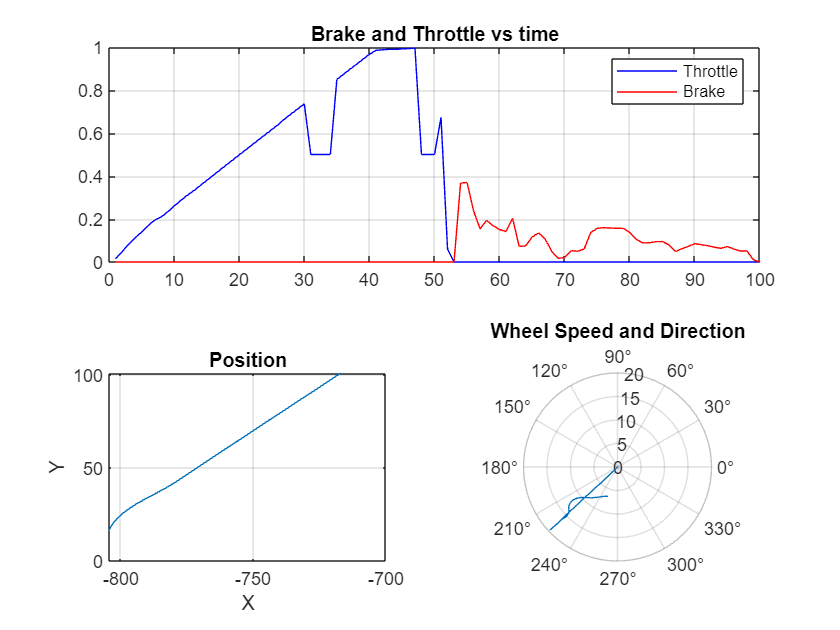

subplot(2, 2, [1 2])
plot(throttles, 'b')
hold on
plot(brakes, 'r')
grid on
legend('Throttle', 'Brake')
title('Brake and Throttle vs time')

subplot 223
plot(positions(:, 1), positions(:, 2))
grid on
title('Position')
xlabel('X')
ylabel('Y')

subplot 224
angles = atan2(directions(:, 2), directions(:, 1));
polarplot(angles, wheel_speeds)
grid on
title('Wheel Speed and Direction')